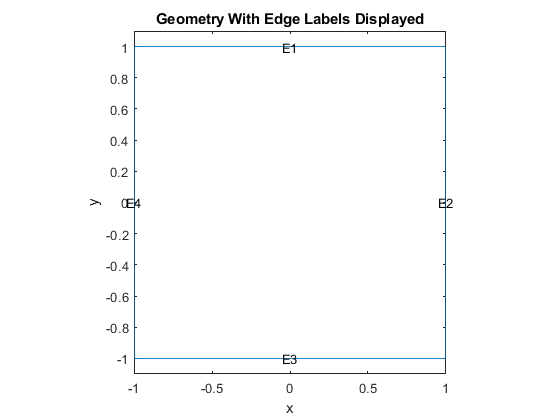

% Wave Equation
% Jesus Martinez A01283785
% Genaro Gallardo A01382459
% Carlos Lopez A01283855
% Clauda Gonzalez A01411506
% Mario Castro A00826824

% Se definen los coeficientes de la ecuacion de onda estandar
c = 1;
a = 0;
f = 0;
m = 1;
% Se describe el modelo con geometria descrita con la funcion "squareg"
numberOfPDE = 1;
model = createpde(numberOfPDE);
geometryFromEdges(model,@squareg);
pdegplot(model,'EdgeLabels','on'); 
ylim([-1.1 1.1]);
axis equal
title 'Geometry With Edge Labels Displayed';
xlabel x
ylabel y

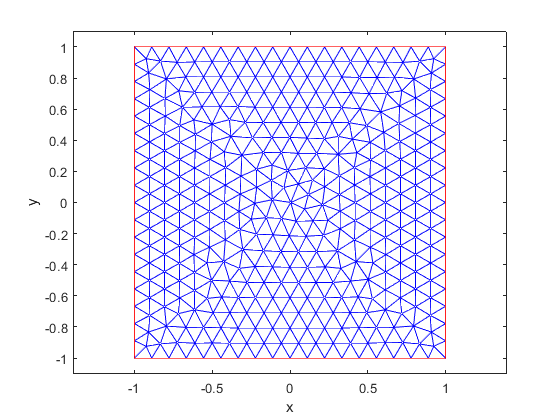

% Se especifican los coeficientes PDE
specifyCoefficients(model,'m',m,'d',0,'c',c,'a',a,'f',f);
% Se especifican las "boundary conditions" para dirichlet y neumann
applyBoundaryCondition(model,'dirichlet','Edge',[2,4],'u',0);
applyBoundaryCondition(model,'neumann','Edge',([1 3]),'g',0);
% Plot del mesh del modelo definido
generateMesh(model);
figure
pdemesh(model);
ylim([-1.1 1.1]);
axis equal
xlabel x
ylabel y

% Declaracion de las condiciones iniciales
u0 = @(location) atan(cos(pi/2*location.x));
ut0 = @(location) 3*sin(pi*location.x).*exp(sin(pi/2*location.y));
setInitialConditions(model,u0,ut0);
% Se definen 31 puntos equitativamente espaciados
n = 31;
tlist = linspace(0,5,n);
model.SolverOptions.ReportStatistics ='on';
result = solvepde(model,tlist);

459 successful steps
38 failed attempts
996 function evaluations
1 partial derivatives
114 LU decompositions
995 solutions of linear systems


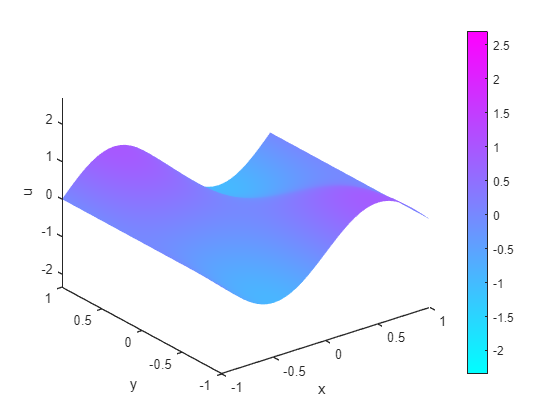

u = result.NodalSolution;
% Creacion de la animacion para visualizar la solucion en todos los steps
figure
umax = max(max(u));
umin = min(min(u));
for i = 1:n
    pdeplot(model,'XYData',u(:,i),'ZData',u(:,i), ...
                  'ZStyle','continuous','Mesh','off');
    axis([-1 1 -1 1 umin umax]); 
    caxis([umin umax]);
    xlabel x
    ylabel y
    zlabel u
    M(i) = getframe;
end